%% ACS 523 Project 1 — Modal Parameter Estimation
% Max Duverneuil
% Requirements:
%  - orthogonal_rev1.m on MATLAB path
%  - ModalData_HammerAccel_TimeHistories.mat in current folder


%% -------------------------------
% PART 1
% -------------------------------

fprintf('\n====================\nPART 1: SDOF + RFP\n====================\n');


PART 1: SDOF + RFP



% SDOF parameters
m_sdof   = 1;      % kg
k_sdof   = 25;     % kg/s^2
eta_true = 0.1;    % loss factor (structural)
w0_true  = sqrt(k_sdof/m_sdof); % rad/s
fprintf('w0 = %.4f rad/s\n', w0_true);

w0 = 5.0000 rad/s



% Frequency grid (Hz) + omega (rad/s)
f1 = linspace(0, 10, 1000).';
w1 = 2*pi*f1;

% Structural damping receptance (Eq 4 form you used)
alpha = (1/m_sdof) ./ (w0_true^2*(1 + 1i*eta_true) - w1.^2);

% Peak picking (magnitude)
[peak_val, idx_pk] = max(abs(alpha));
wn_pp = w1(idx_pk);

% Half-power bandwidth (3 dB down)
target = peak_val/sqrt(2);
[~, idx_a] = min(abs(abs(alpha(1:idx_pk)) - target));
[~, idx_b_rel] = min(abs(abs(alpha(idx_pk:end)) - target));
idx_b = idx_b_rel + idx_pk - 1;

wa = w1(idx_a);
wb = w1(idx_b);

eta_pp = (wb^2 - wa^2) / (2*wn_pp^2);

fprintf('\n--- Peak Picking Results ---\n');


--- Peak Picking Results ---


fprintf('wn (peak-pick) = %.4f rad/s\n', wn_pp);

wn (peak-pick) = 4.9687 rad/s


fprintf('eta (half-power) = %.4f\n', eta_pp);

eta (half-power) = 0.1013



% ---- SISO RFP fit (low order SDOF) ----
Omega1 = w1 / max(w1);    % scaled frequency (dimensionless)
n_den  = 2;               % denominator degree
m_num  = 1;               % numerator degree

[Phi,  T_ac] = orthogonal_rev1(alpha, Omega1, 1, m_num);
[Theta,T_bd] = orthogonal_rev1(alpha, Omega1, 2, n_den);

% Matrices per R&F setup
X = real(Phi' * (alpha .* Theta(:,1:n_den)));
H = real(Phi' * (alpha .* Theta(:,n_den+1)));

% Factor-of-2 correction (per Canvas note)
d = (eye(n_den) - 4*(X'*X)) \ (4*X'*H);
c = 2*(H - X*d);

% Convert orthogonal coefficients -> standard polynomial coefficients
a_coeffs = T_ac * c;         % numerator standard coeffs
b_coeffs = T_bd * [d; 1];    % denominator standard coeffs

% FRF reconstruction check
s_scaled = 1i*Omega1; % s in scaled domain
num_fit  = polyval(flip(a_coeffs), s_scaled);
den_fit  = polyval(flip(b_coeffs), s_scaled);
alpha_fit = num_fit ./ den_fit;

% ---- Pole extraction (FIXED) ----
poles_scaled = roots(flip(b_coeffs));

% Convert to physical rad/s IF your polynomial is in terms of s_scaled = j*(w/max(w))
poles_phys = poles_scaled * max(w1);

% Keep upper half-plane poles
p_hp = poles_phys(imag(poles_phys) > 0);

% Choose the pole closest to peak-picked wn
[~,ii] = min(abs(abs(p_hp) - wn_pp));
p_sel = p_hp(ii);

wn_rfp_1  = abs(p_sel);
eta_rfp_1 = 2 * (-real(p_sel)) / wn_rfp_1;

fprintf('\n--- Part 1 Parameter Comparison ---\n');


--- Part 1 Parameter Comparison ---


fprintf('Method      | wn (rad/s) | eta\n');

Method      | wn (rad/s) | eta


fprintf('Peak-Pick   | %10.4f | %.4f\n', wn_pp, eta_pp);

Peak-Pick   |     4.9687 | 0.1013


fprintf('RFP Poles   | %10.4f | %.4f\n', wn_rfp_1, eta_rfp_1);

RFP Poles   |     5.0004 | 0.0983


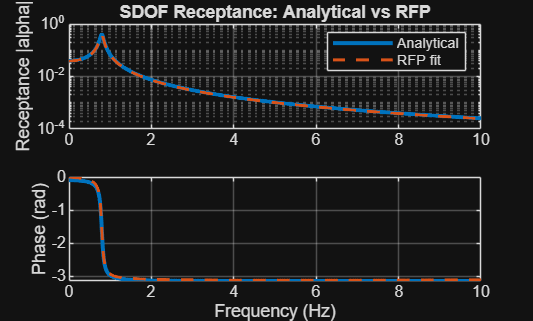


% Part 1 plots
figure('Name','Part 1: RFP Fit Verification');
subplot(2,1,1);
semilogy(f1, abs(alpha), 'k','LineWidth',2,'Color',[0 0.447 0.741]);hold on;
semilogy(f1, abs(alpha_fit), 'r--','LineWidth',1.5,'Color',[0.85 0.325 0.098]);
grid on; ylabel('Receptance |alpha|'); legend('Analytical','RFP fit');
title('SDOF Receptance: Analytical vs RFP');

subplot(2,1,2);
plot(f1, angle(alpha), 'k','LineWidth',2,'Color',[0 0.447 0.741]); hold on;
plot(f1, angle(alpha_fit), 'r--','LineWidth',1.5,'Color',[0.85 0.325 0.098]);
grid on; xlabel('Frequency (Hz)'); ylabel('Phase (rad)');


%% -------------------------------
% PART 2
% -------------------------------

fprintf('\n====================\nPART 2: Experimental FRF\n====================\n');


PART 2: Experimental FRF



load('ModalData_HammerAccel_TimeHistories.mat');

Error using load
ModalData_HammerAccel_TimeHistories.mat is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\maxfd\OneDrive\Documents\MATLAB\ACS-523-SP-26\Module-1-Project-1

Change the MATLAB current folder or add its folder to the MATLAB path.


% Calibration (V -> SI)
S_hammer = hammer_mV_per_N / 1000;         % V/N
S_accel  = accel_mV_per_m_per_s2 / 1000;   % V/(m/s^2)
hammer_N    = hammer_data_Volts / S_hammer;
accel_mps2  = accel_data_Volts / S_accel;

fs = sample_rate;
N  = N_samples;
dt = 1/fs;
df = fs/N;

f_vec = (0:N/2).' * df;
w_vec = 2*pi*f_vec;

% Averaged spectral densities
Gxx_sum = 0;
Gyy_sum = 0;
Gxy_sum = 0;

win = hann(N);
U = sum(win.^2)/N;
fprintf('Window U = %.4f\n', U);

for i = 1:num_hits
    x = hammer_N(:,i)   .* win;
    y = accel_mps2(:,i) .* win;

    X = fft(x) * dt;
    Y = fft(y) * dt;

    Sxx = (1/(N*dt)) * (X .* conj(X)) / U;
    Syy = (1/(N*dt)) * (Y .* conj(Y)) / U;
    Sxy = (1/(N*dt)) * (conj(X) .* Y) / U;

    Gxx_sum = Gxx_sum + 2*Sxx(1:N/2+1);
    Gyy_sum = Gyy_sum + 2*Syy(1:N/2+1);
    Gxy_sum = Gxy_sum + 2*Sxy(1:N/2+1);
end

Gxx = Gxx_sum/num_hits;
Gyy = Gyy_sum/num_hits;
Gxy = Gxy_sum/num_hits;

% H1 estimator: inertance (a/F)
H_inertance = Gxy ./ Gxx;

% Convert inertance -> receptance: x/F = (a/F)/(-w^2)
H_receptance = H_inertance ./ (-w_vec.^2);
H_receptance(1:5) = 0; % avoid division blow-up near DC

% Coherence
coherence = (abs(Gxy).^2) ./ (Gxx .* Gyy);

% Part 2 plots
figure('Name','Part 2: Experimental Transfer Function');
subplot(3,1,1);
semilogy(f_vec, abs(H_receptance), 'LineWidth',1.2);
grid on; ylabel('Receptance |alpha| (m/N)');
title('Experimental Transfer Function: Aluminum Plate');

subplot(3,1,2);
plot(f_vec, angle(H_receptance), 'LineWidth',1.0);
grid on; ylabel('Phase (rad)'); xlabel('Frequency (Hz)');

subplot(3,1,3);
plot(f_vec, coherence, 'LineWidth',1.0);
ylim([0 1.05]); grid on;
ylabel('Coherence'); xlabel('Frequency (Hz)');

% Canonical expected fundamental frequency
E = 70e9;
nu = 0.33;
rho_vol = 2700;
h_plate = 0.02;

D = (E*h_plate^3) / (12*(1 - nu^2));
lambda = 13.47;
Lx = 0.270;

f_expected = (lambda/(Lx^2)) * sqrt(D/(rho_vol*h_plate)) / (2*pi);
fprintf('\nCanonical expected fundamental frequency: %.2f Hz\n', f_expected);

% Estimates "measured fundamental" as first strong resonance peak above 100 Hz

magH = abs(H_receptance);
mask = (f_vec > 100) & (f_vec < 2000);
[pk_vals, pk_locs] = findpeaks(magH(mask), f_vec(mask), 'MinPeakProminence', max(magH(mask))*0.02);

if ~isempty(pk_locs)
    f_meas1 = pk_locs(1);
    err_pct = 100*abs(f_meas1 - f_expected)/f_expected;
    fprintf('Measured first strong peak (auto): %.2f Hz (error %.1f%%)\n', f_meas1, err_pct);
else
    fprintf('Measured first peak auto-detect: could not robustly detect (adjust MinPeakProminence).\n');
end

%% -------------------------------
% PART 3
% -------------------------------

fprintf('\n====================\nPART 3: First 4 Flexible Modes\n====================\n');

% Plate modal mass approximation
Lx = 0.270; Ly = 0.380; h = 0.020; rho = 2700;
modal_mass = (rho*h*Lx*Ly)/4;

% --- 4 mode peak frequencies ---
fn_peaks = [805.7; 1806.3; 2746.9; 3974.1];  % Hz

% Half-power eta estimates around each peak
eta_hp = zeros(size(fn_peaks));

for r = 1:numel(fn_peaks)
    [~, idx_p] = min(abs(f_vec - fn_peaks(r)));
    peak_val = abs(H_receptance(idx_p));
    target = peak_val/sqrt(2);

    % Searches left and right for target crossings
    [~, idx_a] = min(abs(abs(H_receptance(1:idx_p)) - target));
    [~, idx_b_rel] = min(abs(abs(H_receptance(idx_p:end)) - target));
    idx_b = idx_b_rel + idx_p - 1;

    wa = 2*pi*f_vec(idx_a);
    wb = 2*pi*f_vec(idx_b);
    wn_r = 2*pi*fn_peaks(r);

    eta_hp(r) = (wb^2 - wa^2) / (2*wn_r^2);
end

T_hp = table((1:4).', fn_peaks, eta_hp, 'VariableNames', {'Mode','PeakFreq_Hz','Eta_HalfPower'});
disp('--- Half-Power Estimates (Experimental) ---');
disp(T_hp);

% Eq(5) SDOF summation (tuned q's)
qr_tuned = [0.12, 0.25, 0.18, 0.20];  % tune as needed
H_sum = zeros(size(H_receptance));

for r = 1:4
    wr = 2*pi*fn_peaks(r);
    H_sum = H_sum + (1/modal_mass) * (qr_tuned(r) ./ (wr^2*(1 + 1i*eta_hp(r)) - w_vec.^2));
end

% --- RFP fit for MDOF  ---
Omega3 = w_vec / max(w_vec);

n_poly = 10;
m_poly = 9;

[Phi3,  T_ac3] = orthogonal_rev1(H_receptance, Omega3, 1, m_poly);
[Theta3,T_bd3] = orthogonal_rev1(H_receptance, Omega3, 2, n_poly);

X3 = 2*real(Phi3' * (H_receptance .* Theta3(:,1:n_poly)));
H3 = 2*real(Phi3' * (H_receptance .* Theta3(:,n_poly+1)));

d3 = (eye(n_poly) - (X3'*X3)) \ (X3'*H3);
b_std = T_bd3 * [d3; 1];

c3 = H3 - X3*d3;
a_std = T_ac3 * c3;

% reconstruct RFP fit
s_scaled3 = 1i*Omega3;
H_fit = polyval(flip(a_std), s_scaled3) ./ polyval(flip(b_std), s_scaled3);

% Poles (MDOF)
poles_scaled3 = roots(flip(b_std));
poles_phys3   = poles_scaled3 * max(w_vec);

p_hp3 = poles_phys3(imag(poles_phys3) > 0);
[~, idx_sort] = sort(imag(p_hp3));
p_sorted = p_hp3(idx_sort);

wn_rfp3 = abs(p_sorted);
fn_rfp3 = wn_rfp3/(2*pi);
eta_rfp3 = 2*(-real(p_sorted))./wn_rfp3;

Results = table((1:length(fn_rfp3)).', fn_rfp3, eta_rfp3, ...
    'VariableNames', {'Mode','Frequency_Hz','Loss_Factor'});
disp('--- RFP Extracted Modal Parameters (all positive-imag poles) ---');
disp(Results);

% Picks the 4 poles closest to my above hard-coded 4 peaks for comparison
fn_rfp4 = zeros(4,1);
eta_rfp4 = zeros(4,1);

for r = 1:4
    [~,ii] = min(abs(fn_rfp3 - fn_peaks(r)));
    fn_rfp4(r)  = fn_rfp3(ii);
    eta_rfp4(r) = eta_rfp3(ii);
end

T_compare = table((1:4).', fn_peaks, eta_hp, fn_rfp4, eta_rfp4, ...
    'VariableNames', {'Mode','PeakFreq_Hz','Eta_HalfPower','RFP_Freq_Hz','RFP_Eta'});
disp('--- Mode-by-Mode Comparison (Half-Power vs Closest RFP Pole) ---');
disp(T_compare);

% Final overlay plot (Experimental vs SDOF sum vs RFP)
figure('Name','Part 3: MDOF Comparison');
semilogy(f_vec, abs(H_receptance), 'k', 'LineWidth',1.4); hold on;
semilogy(f_vec, abs(H_sum),       'b--','LineWidth',1.2);
semilogy(f_vec, abs(H_fit),       'r:','LineWidth',1.6);
grid on;
xlabel('Frequency (Hz)'); ylabel('Receptance Magnitude (m/N)');
legend('Experimental Data','SDOF Summation (Eq 5)','RFP Fit','Location','northeast');
title('MDOF Comparison: Experimental vs SDOF Sum vs RFP Fit');

